# Computer Vision Lab 2

# Edges and contours

**Authors**: Jorge Alexander and Emer Rodriguez Formisano

**Date**: 23th October 2017

## 1. Determine the optimal edges

Create a file "exercise1.m" to implement the following steps:

- � Read the image "starbuck.jpg" and find its edges using matlab function edge.

-  Apply different operators (Sobel and Prewitt, Laplacian of Gaussian) and find the optimal parameters for each of them.

- Apply Canny edge detector (also implemented in the function edge).

- Overlap the edges on the image as shown in Fig.2 (right).

- Repeat the experiment on 3 other images.

Function showedges applies the previous points programatically for each imge and plot the results. Here is applied to:

**Starbucks**

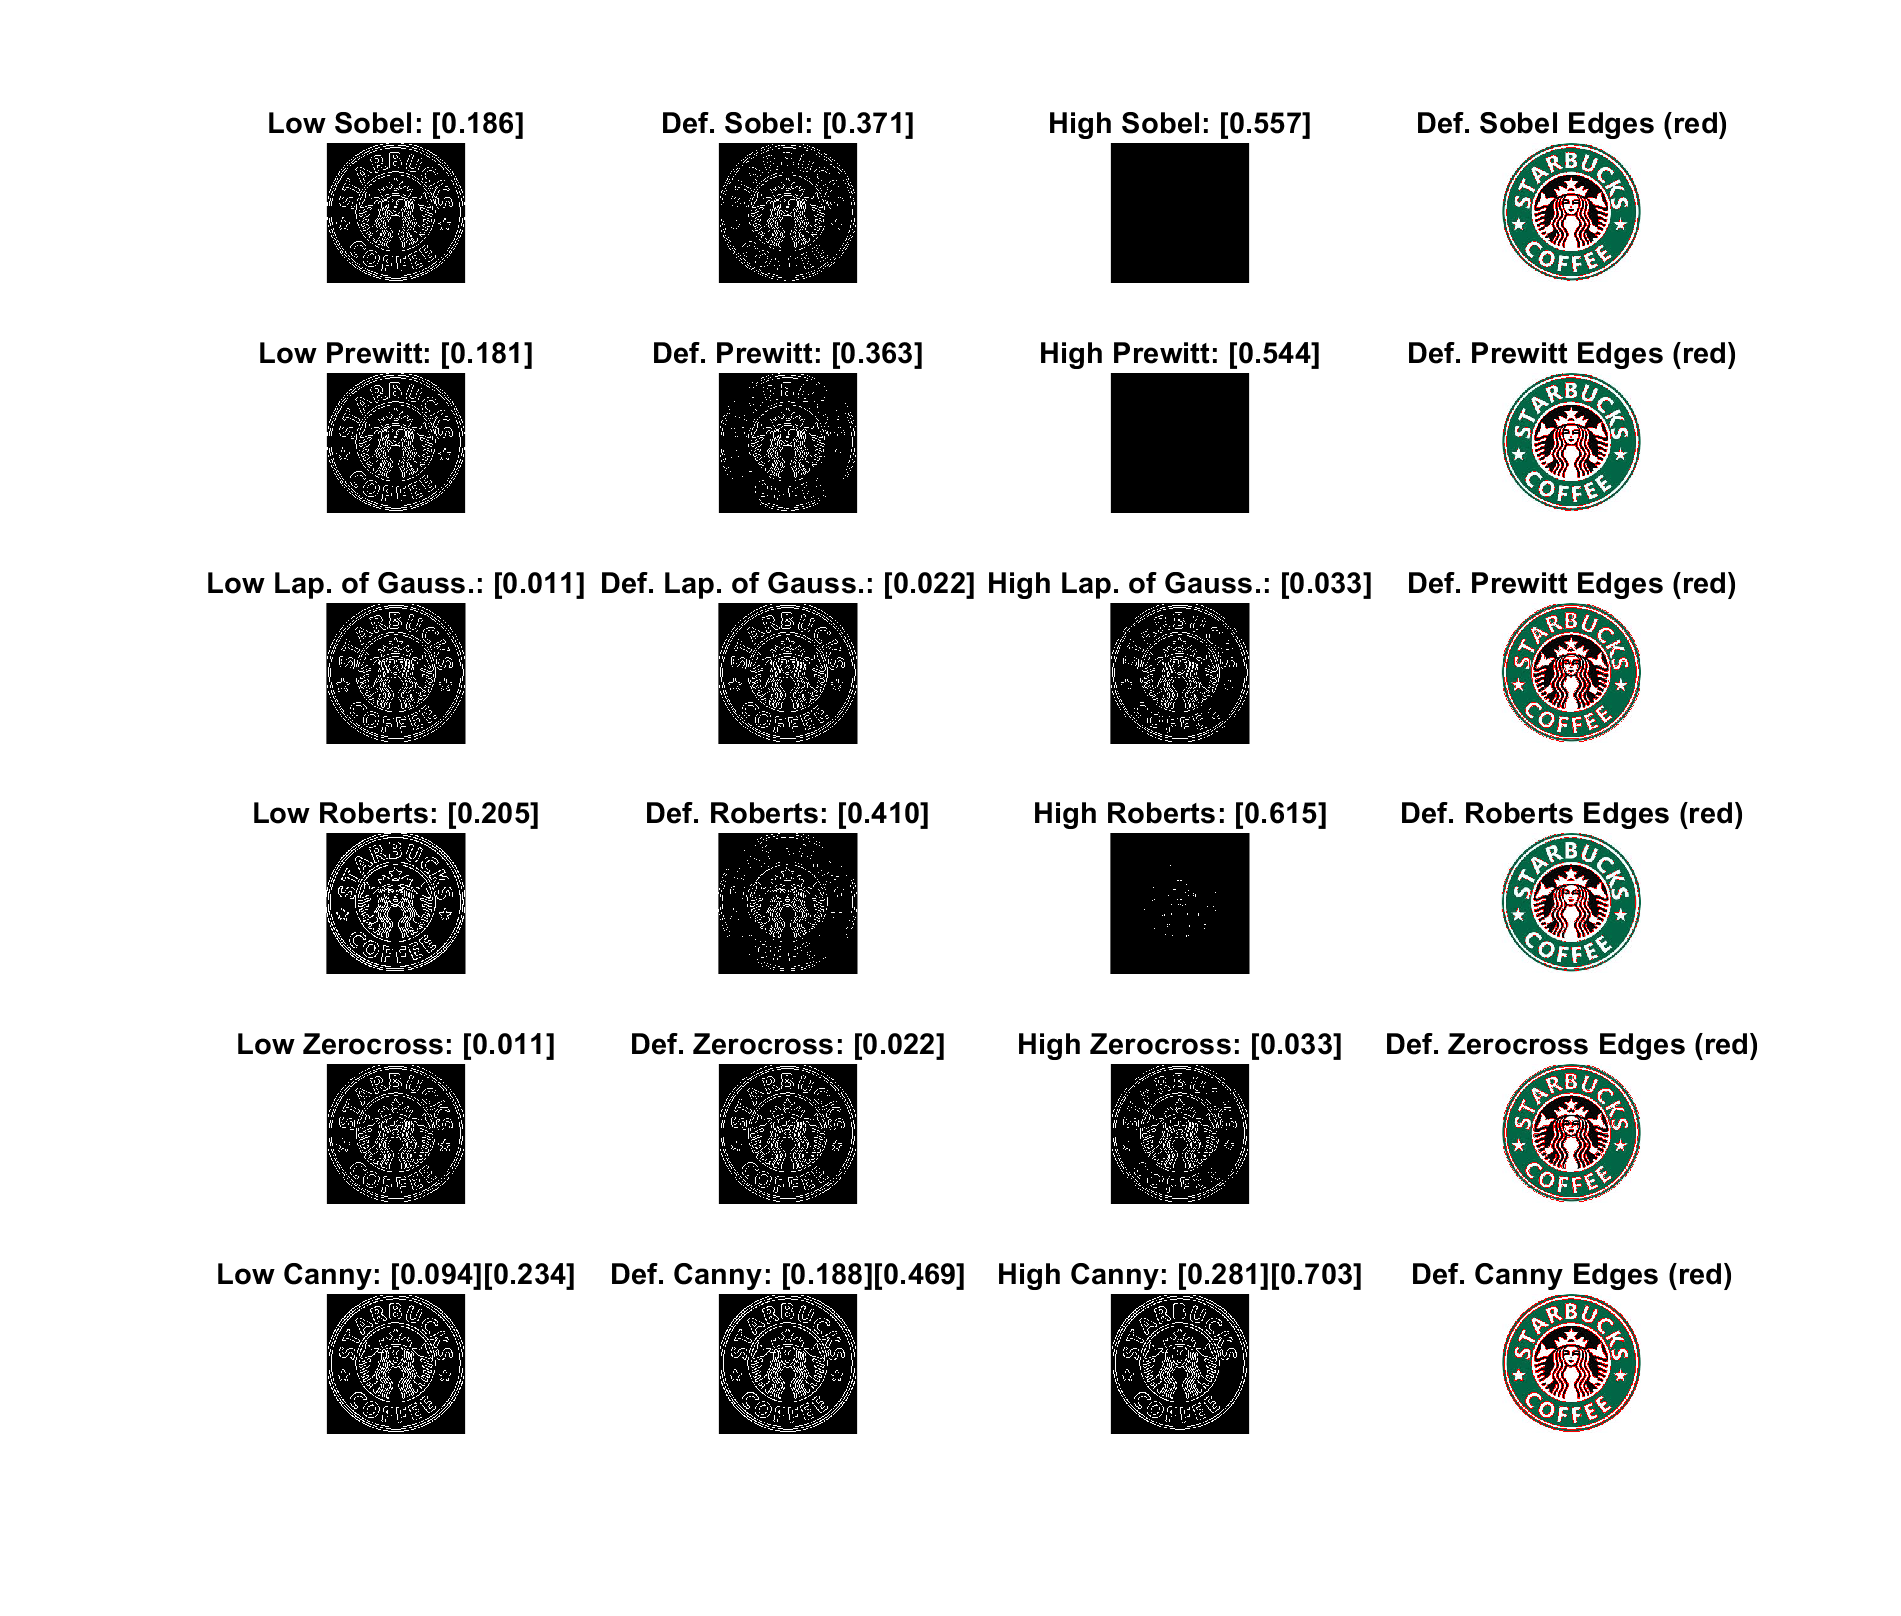

set(gcf,'Position',[0 0 1000 850]);
showedges('./images_video/starbuck.jpg')

**Doulphin**

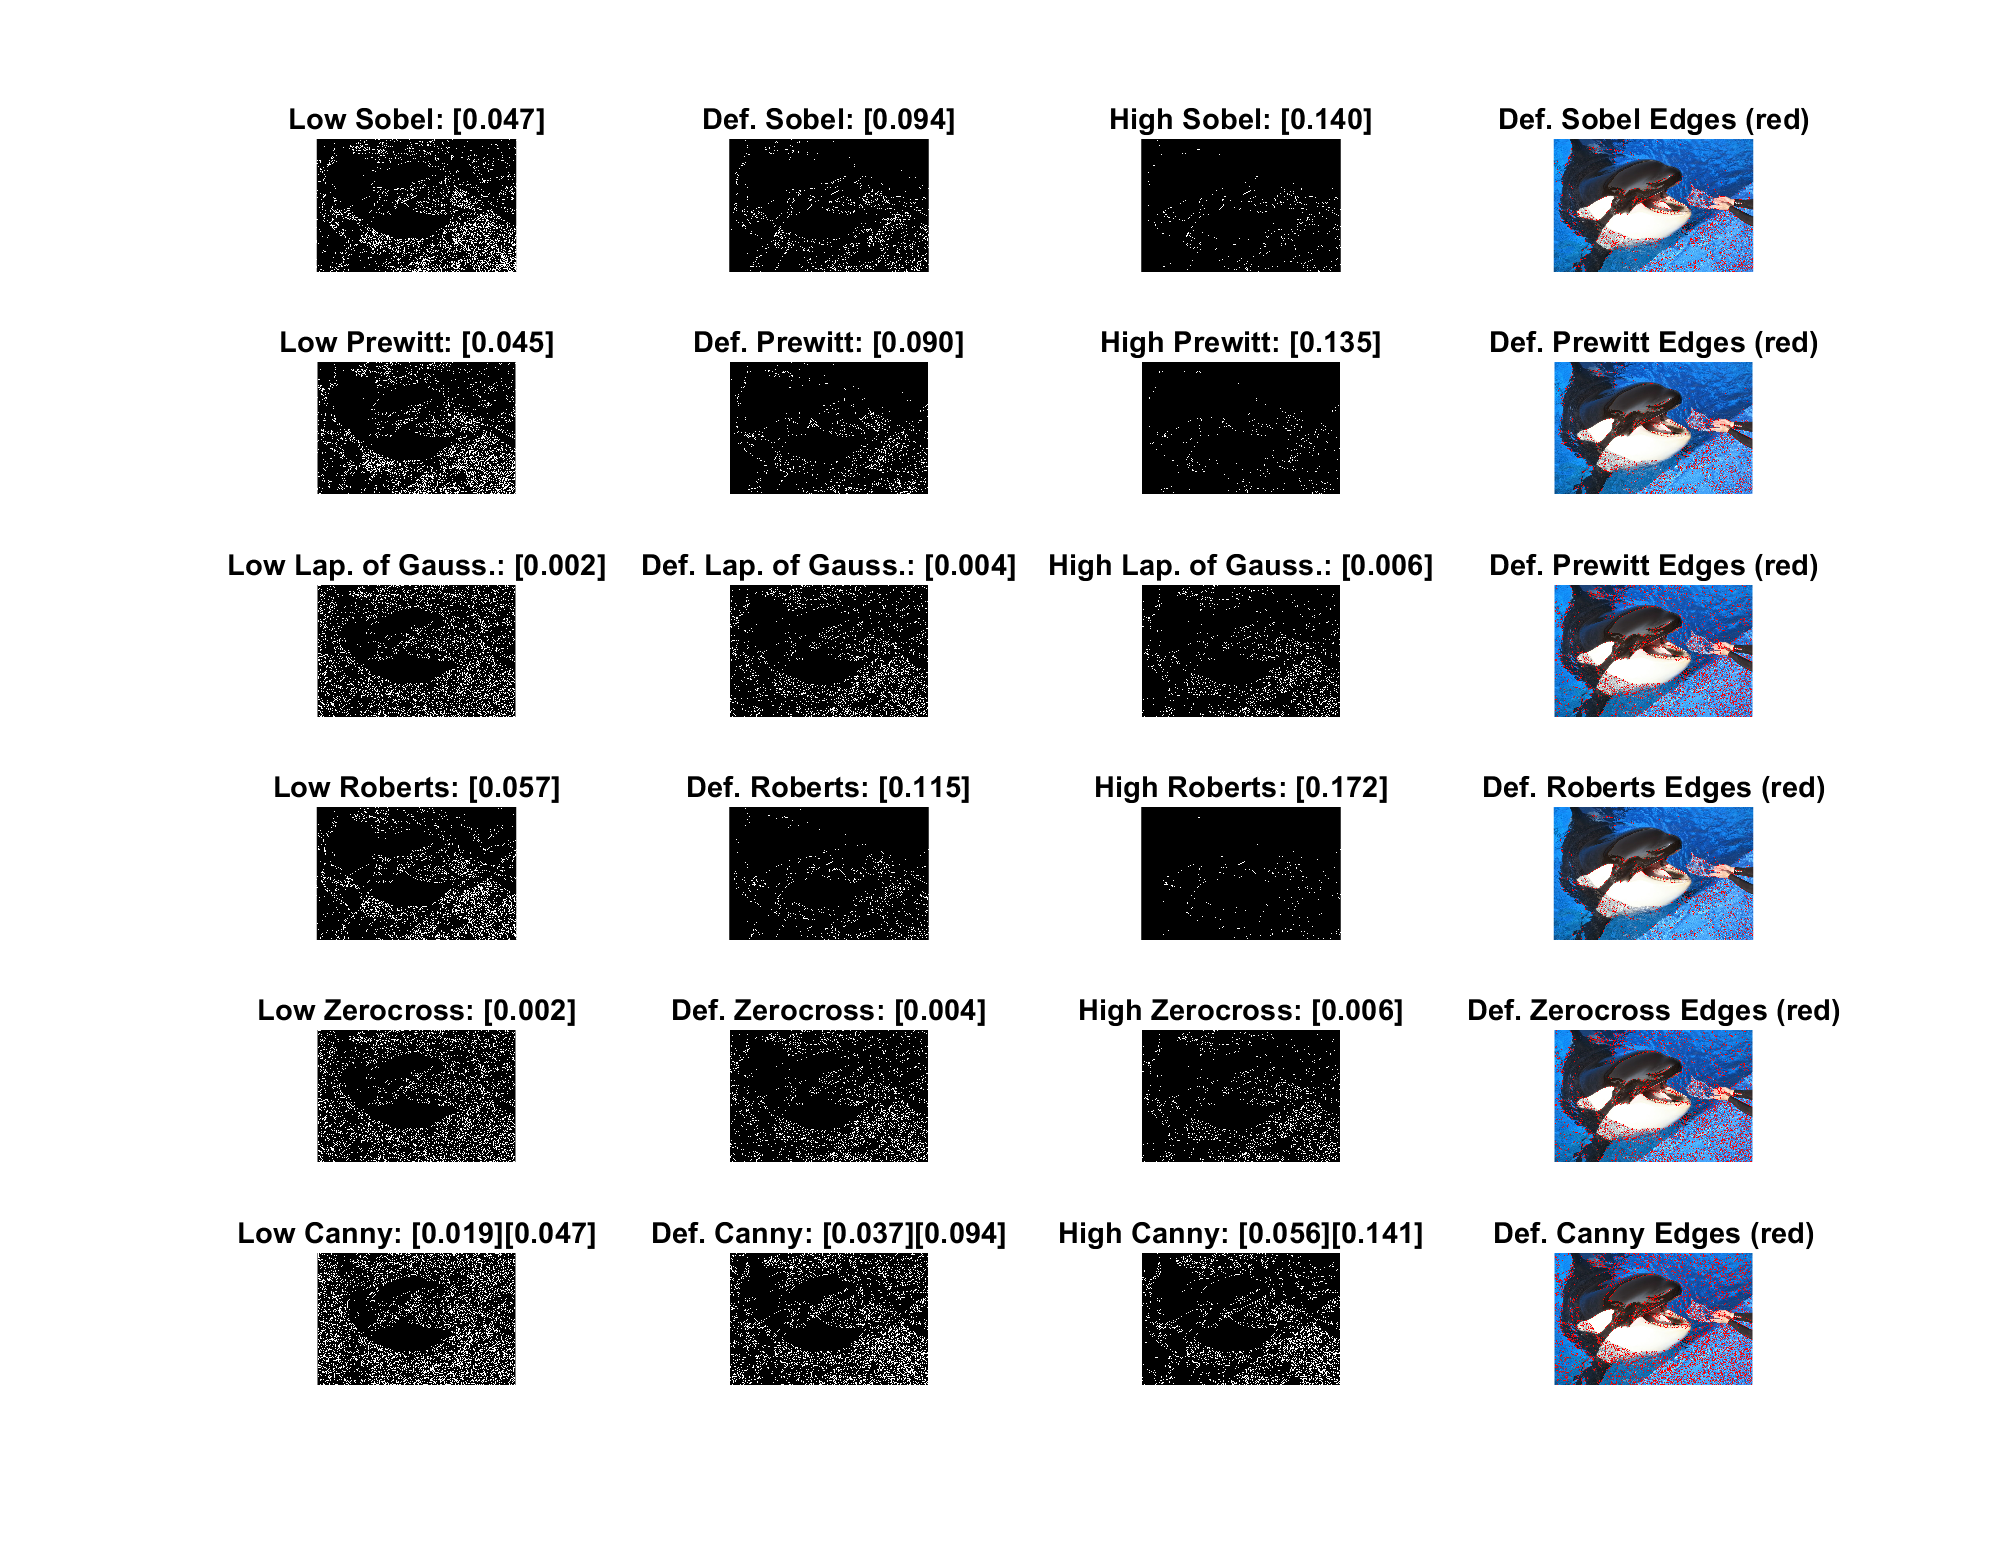

showedges('./images_video/Doulphin.jpg')

**Einstein**

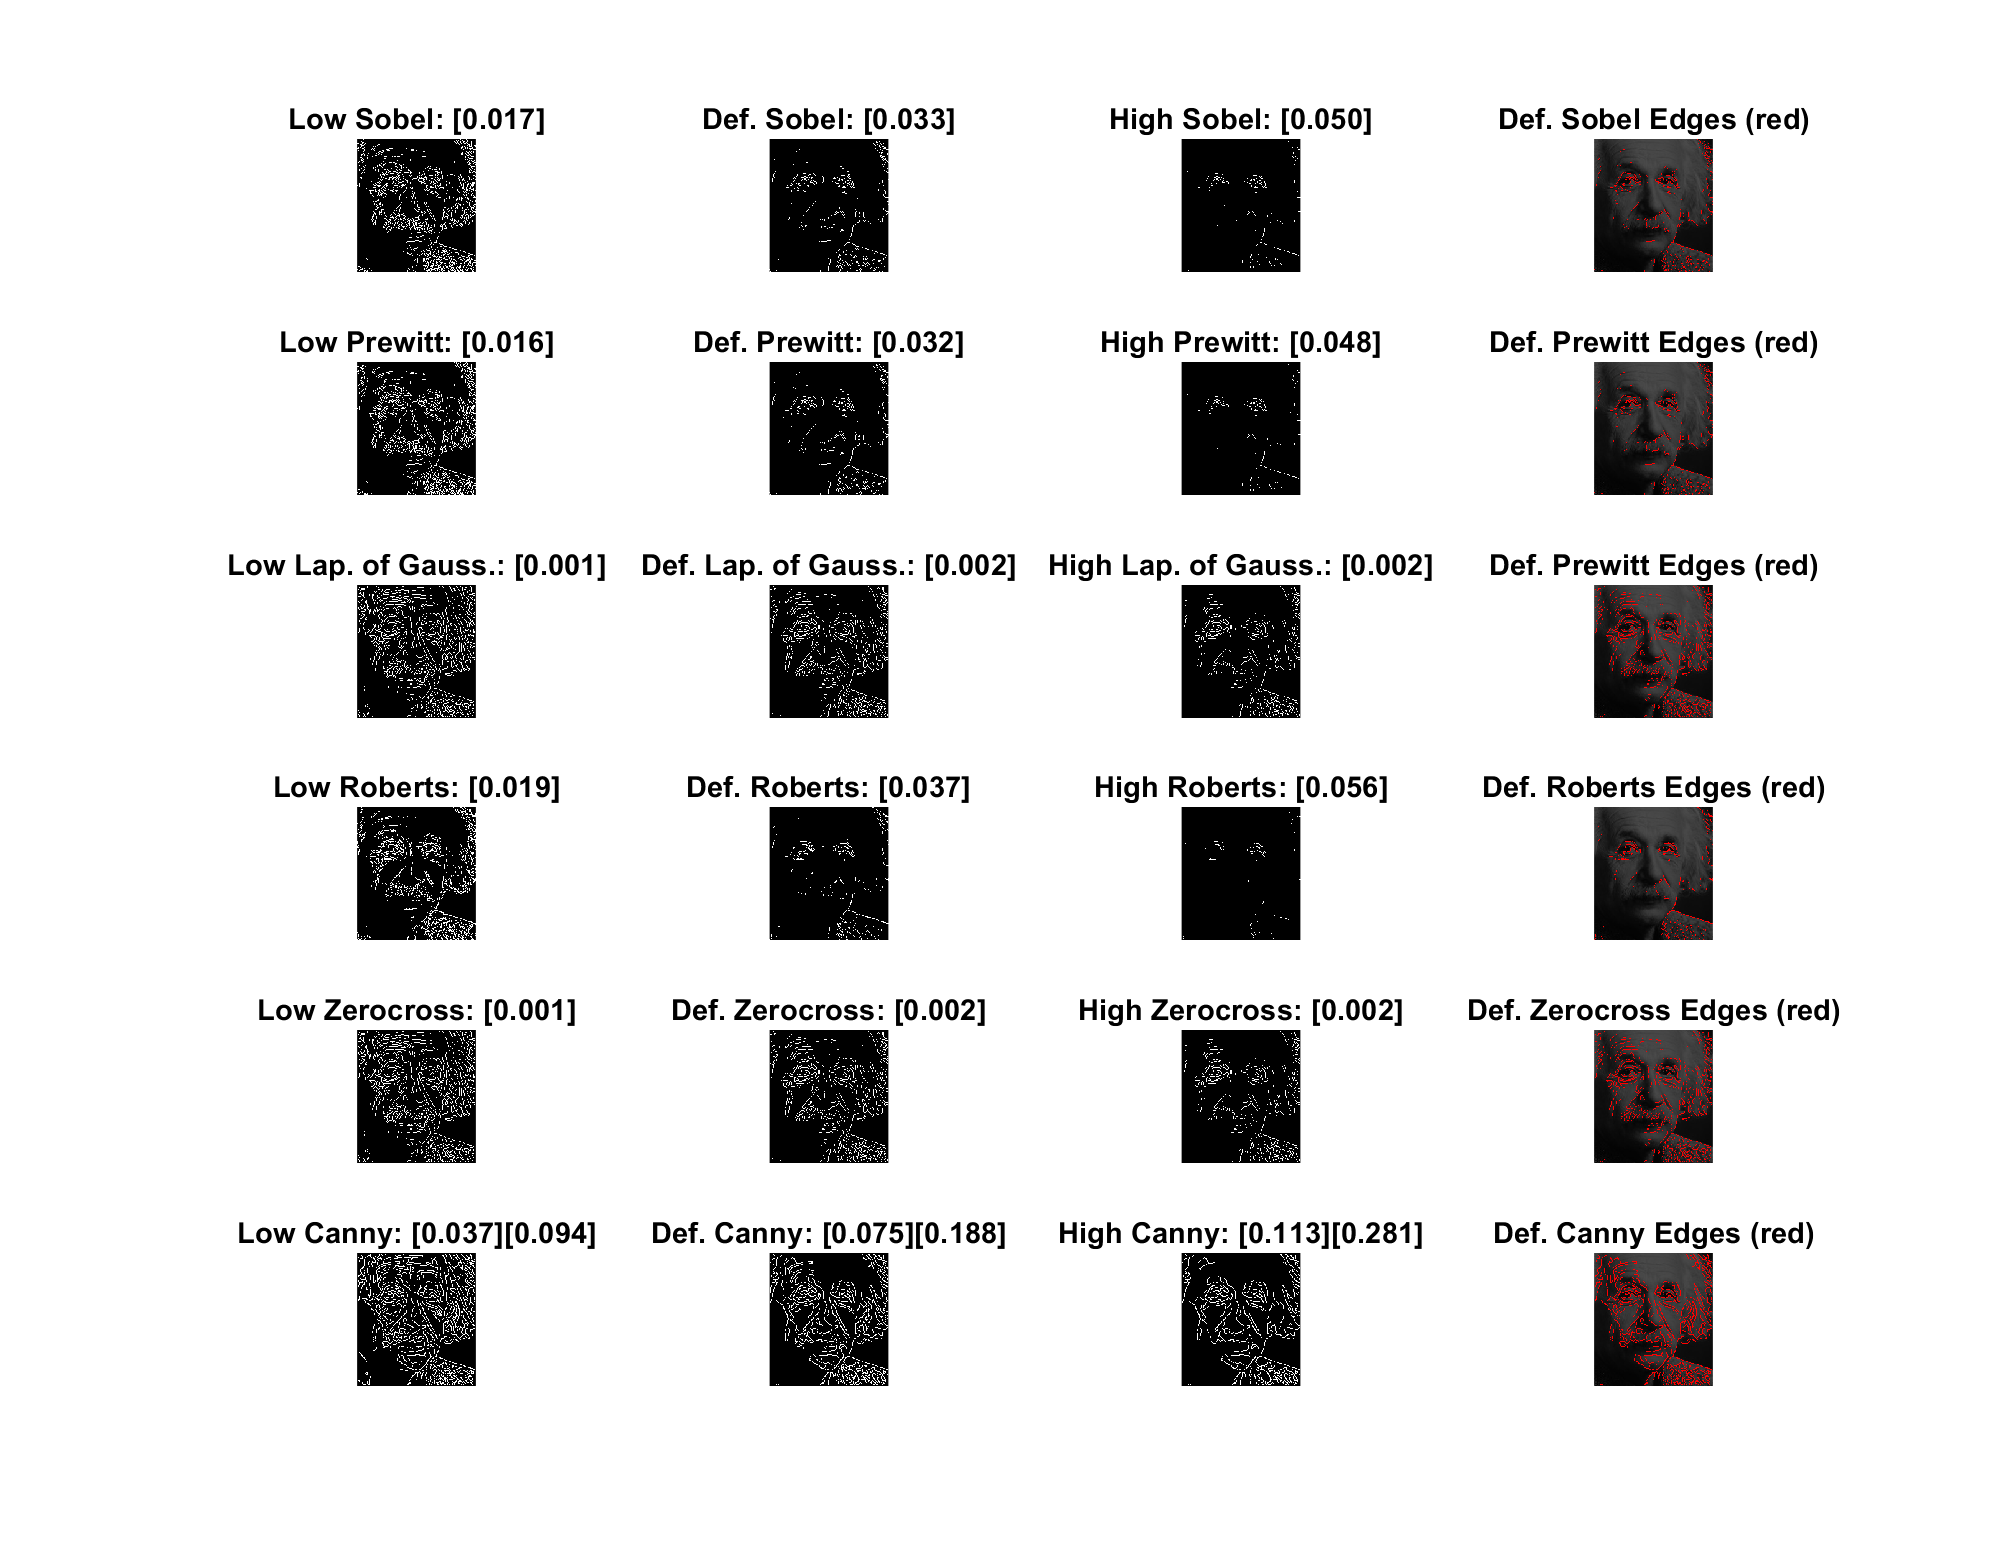

showedges('./images_video/Einstein.jpg')

Answer the following questions in the report:

1. How many methods to obtain the edges of the image are implemented by the function edge?

2. Which is the best edge detector?

3. What are the advantages and disadvantages you see when extracting the edges on the different images?

4. Discuss if the parameters should be changed for the different images.

## Defined Functions

function showedges(imageFilename)
%UNTITLED2 Summary of this function goes here
%   Detailed explanation goes here

    function overlapedImage = overlapedges(rgbImage, edges)
        redCh = rgbImage(:,:,1);
        greenCh = rgbImage(:,:,2);
        blueCh = rgbImage(:,:,3);
        redCh(edges) = 255;
        greenCh(edges) = 0;
        blueCh(edges) = 0;
        overlapedImage = cat(3, redCh, greenCh, blueCh);      
    end

rawImage = imread(imageFilename);
if(ndims(rawImage)==2)
    ch = rawImage ./ 3;
    % Gray as RGB representation
    rawImage = cat(3, ch, ch, ch);
end
rawImageGray = rgb2gray(rawImage);

fixedThres = [];
multThres = [0.5, 1.5];
sigma = 2;
direction = 'both';
thinning = 'thinning'; 
% Sobel
[sobel, sobelThres] = edge(rawImageGray, 'Sobel', fixedThres, direction, thinning);
[sobelLow, sobelThresLow] = edge(rawImageGray, 'Sobel', sobelThres * multThres(1), direction, thinning);
[sobelHigh, sobelThresHigh] = edge(rawImageGray, 'Sobel', sobelThres * multThres(2), direction, thinning);

% Prewitt
[prewitt, prewittThres] = edge(rawImageGray, 'Prewitt', fixedThres, direction, thinning);
[prewittLow, prewittThresLow] = edge(rawImageGray, 'Prewitt', prewittThres * multThres(1), direction, thinning);
[prewittHigh, prewittThresHigh] = edge(rawImageGray, 'Prewitt', prewittThres * multThres(2), direction, thinning);

% Lapacian of Gaussian
[log, logThres] = edge(rawImageGray, 'log', fixedThres, sigma);
[logLow, logThresLow] = edge(rawImageGray, 'log', logThres * multThres(1), sigma);
[logHigh, logThresHigh] = edge(rawImageGray, 'log', logThres * multThres(2), sigma);

% Roberts
[roberts, robertsThres]  = edge(rawImageGray, 'Roberts', fixedThres);
[robertsLow, robertsThresLow]  = edge(rawImageGray, 'Roberts', robertsThres * multThres(1));
[robertsHigh, robertsThresHigh]  = edge(rawImageGray, 'Roberts', robertsThres * multThres(2));

% ZeroCross
[zerocross, zerocrossThres] = edge(rawImageGray, 'zerocross', fixedThres);
[zerocrossLow, zerocrossThresLow] = edge(rawImageGray, 'zerocross', zerocrossThres * multThres(1));
[zerocrossHigh, zerocrossThresHigh] = edge(rawImageGray, 'zerocross', zerocrossThres * multThres(2));

% Canny
[canny, cannyThres] = edge(rawImageGray, 'Canny', fixedThres);
[cannyLow, cannyThresLow] = edge(rawImageGray, 'Canny', cannyThres * multThres(1));
[cannyHigh, cannyThresHigh] = edge(rawImageGray, 'Canny', cannyThres * multThres(2));

% Plots
subplot(6,4,1), imshow(sobelLow), title("Low Sobel: " + sprintf("[%.3f]",string(sobelThresLow))), ... 
subplot(6,4,2), imshow(sobel), title("Def. Sobel: " + sprintf("[%.3f]",string(sobelThres))), ... 
subplot(6,4,3), imshow(sobelHigh), title("High Sobel: " + sprintf("[%.3f]",string(sobelThresHigh))), ... 
subplot(6,4,4), imshow(overlapedges(rawImage, sobel)), title("Def. Sobel Edges (red)"), ...

subplot(6,4,5), imshow(prewittLow), title("Low Prewitt: " + sprintf("[%.3f]",string(prewittThresLow))), ... 
subplot(6,4,6), imshow(prewitt), title("Def. Prewitt: " + sprintf("[%.3f]",string(prewittThres))), ... 
subplot(6,4,7), imshow(prewittHigh), title("High Prewitt: " + sprintf("[%.3f]",string(prewittThresHigh))), ... 
subplot(6,4,8), imshow(overlapedges(rawImage, prewitt)), title("Def. Prewitt Edges (red)"), ...

subplot(6,4,9), imshow(logLow), title("Low Lap. of Gauss.: " + sprintf("[%.3f]",string(logThresLow))), ... 
subplot(6,4,10), imshow(log), title("Def. Lap. of Gauss.: " + sprintf("[%.3f]",string(logThres))), ... 
subplot(6,4,11), imshow(logHigh), title("High Lap. of Gauss.: " + sprintf("[%.3f]",string(logThresHigh))), ... 
subplot(6,4,12), imshow(overlapedges(rawImage, log)), title("Def. Prewitt Edges (red)"), ...

subplot(6,4,13), imshow(robertsLow), title("Low Roberts: " + sprintf("[%.3f]",string(robertsThresLow))), ... 
subplot(6,4,14), imshow(roberts), title("Def. Roberts: " + sprintf("[%.3f]",string(robertsThres))), ... 
subplot(6,4,15), imshow(robertsHigh), title("High Roberts: " + sprintf("[%.3f]",string(robertsThresHigh))), ... 
subplot(6,4,16), imshow(overlapedges(rawImage, roberts)), title("Def. Roberts Edges (red)"), ...

subplot(6,4,17), imshow(zerocrossLow), title("Low Zerocross: " + sprintf("[%.3f]",string(zerocrossThresLow))), ... 
subplot(6,4,18), imshow(zerocross), title("Def. Zerocross: " + sprintf("[%.3f]",string(zerocrossThres))), ... 
subplot(6,4,19), imshow(zerocrossHigh), title("High Zerocross: " + sprintf("[%.3f]",string(zerocrossThresHigh))), ... 
subplot(6,4,20), imshow(overlapedges(rawImage, zerocross)), title("Def. Zerocross Edges (red)"), ...

subplot(6,4,21), imshow(cannyLow), title("Low Canny: " + sprintf("[%.3f]",string(cannyThresLow))), ... 
subplot(6,4,22), imshow(canny), title("Def. Canny: " + sprintf("[%.3f]",string(cannyThres))), ... 
subplot(6,4,23), imshow(cannyHigh), title("High Canny: " + sprintf("[%.3f]",string(cannyThresHigh))), ... 
subplot(6,4,24), imshow(overlapedges(rawImage, canny)), title("Def. Canny Edges (red)");

end
